# Cinéticas de Ozonización

## Experimento 1

Creación de objeto y carga de archivos:

clearvars
close all
clc
exp1 = laiiqatoolbox; % Crea el objeto
exp1.openfiles; % Abre venta de dialogo para seleccionar archivos

Modificación de parámetros:

exp1.title = 'Ozonograma 1'; % Quitamos el titulo
exp1.xlabel = 'min'; % Unidades de tiempo en minutos para el eje x
exp1.xf{1} = 60; % La linea de datos 1 llega hasta 60 min
exp1.legend = {'default'}; % Nombres de leyenda = nombres de archivos

Creación de gráfico:

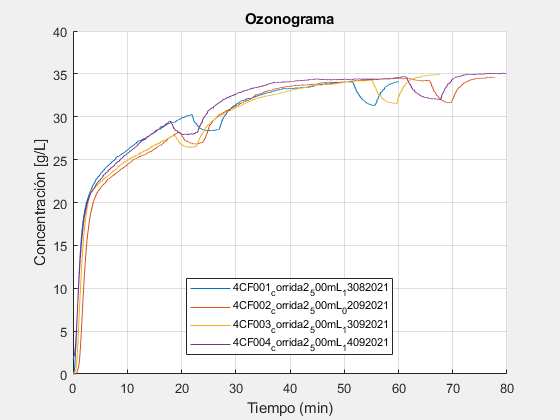

exp1.plotfiles; % Crea el objeto gráfico

Cálculo de consumo de ozono:

exp1.ozonecalc; % Calcula ozono consumido, residual y total para linea de datos

Para 4CF001_corrida2_500mL_13082021:
    Consumido: 0.27064 g/L
    Residual: 1.775 g/L
    Total: 2.0456 g/L en 60 min


Para 4CF002_corrida2_500mL_02092021:
    Consumido: 0.35836 g/L
    Residual: 2.3315 g/L
    Total: 2.6899 g/L en 77.69 min


Para 4CF003_corrida2_500mL_13092021:
    Consumido: 0.36634 g/L
    Residual: 1.995 g/L
    Total: 2.3614 g/L en 67.5538 min


Para 4CF004_corrida2_500mL_14092021:
    Consumido: 0.32065 g/L
    Residual: 2.4804 g/L
    Total: 2.8011 g/L en 79.8092 min




## Experimento 2

Creación de objeto y carga de archivos.

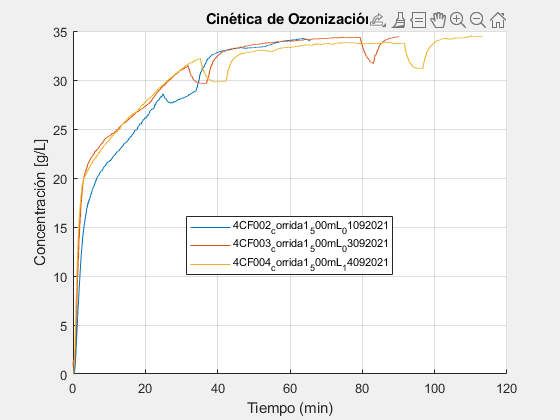

exp2 = laiiqatoolbox;
exp2.openfiles;
exp2.plotfiles;

Modificación de parámetros:

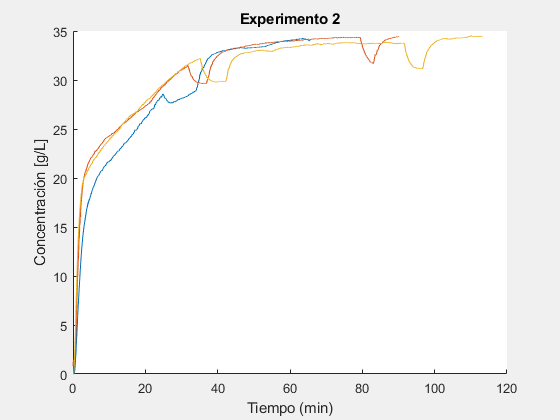

exp2.title = 'Experimento 2';
exp2.legend = {}; % Desactiva las leyendas en el gráfico
exp2.grid = 'off'; % Quita las rejillas
exp2.plotfiles; % Aplica los cambios

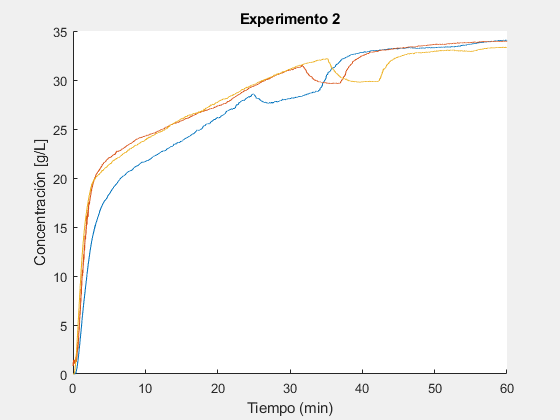

exp2.xf = {60 60 60}; % Delimita todos los datos a 60 minutos
exp2.plotfiles;

Guardado de figuras:

exp1.imageResolution = 800; % Resolución de la imagen de la figura 1 
% default = 300. Solo aplica para imagenes NO vectoriales.
exp2.imageResolution = 600; % Resolución de la imagen de la figura 2
exp2.title = ''; % Quitamos titulo de la figura 2
exp1.saveplot('MiExperimento1.png'); % Nombre y extensión del archivo a guardar

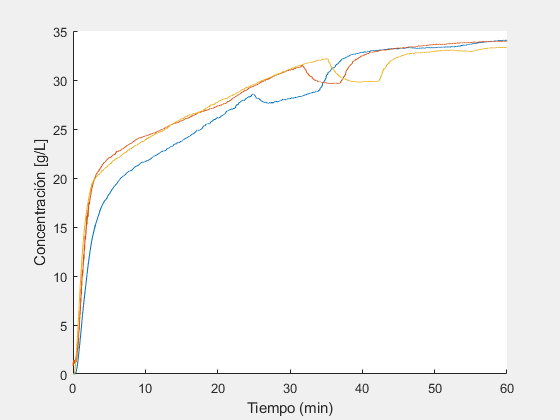

exp2.saveplot('MiExperimento2.png'); % Guardado de figura 2

Cálculo de ozono:

exp2.ozonecalc;

Para 4CF002_corrida1_500mL_01092021:
    Consumido: 0.40078 g/L
    Residual: 1.6434 g/L
    Total: 2.0442 g/L en 60 min


Para 4CF003_corrida1_500mL_03092021:
    Consumido: 0.32002 g/L
    Residual: 1.7193 g/L
    Total: 2.0393 g/L en 60 min


Para 4CF004_corrida1_500mL_14092021:
    Consumido: 0.29838 g/L
    Residual: 1.7036 g/L
    Total: 2.002 g/L en 60 min


